direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

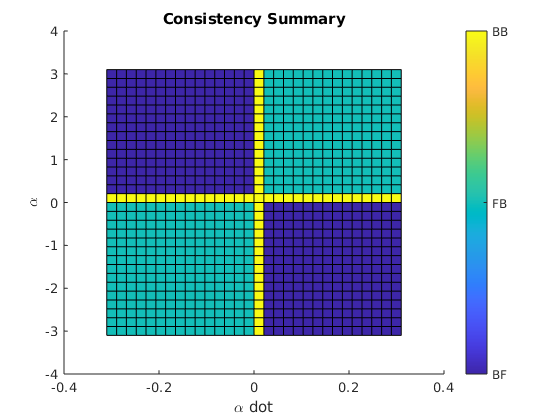

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

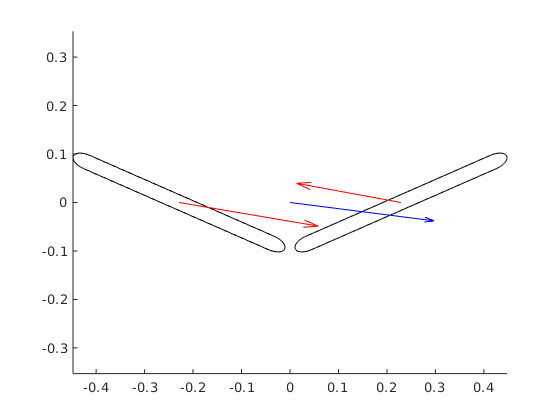

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, 2, 0.1);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% define gait functions
centered_gait = generate_1D_gait(1, 0, 1);
offset_gait = generate_1D_gait(1, 1, 1);
offset_gait2 = generate_1D_gait(1, -1, 1);
tiny_gait = generate_1D_gait(0.5, 0, 1);
tiny_gait_bw = generate_1D_gait(0.5, 0, -1);
huge_gait = generate_1D_gait(3, 0, 1);
huge_gait_bw = generate_1D_gait(3, 0, -1);

gait = tiny_gait;

% apply ODE solver
sol = asym_solve_gait(s, gait, system_map);
gait_displacement = deval(sol, 2*pi)

gait_displacement =     0.0183
    0.0000
    0.0001


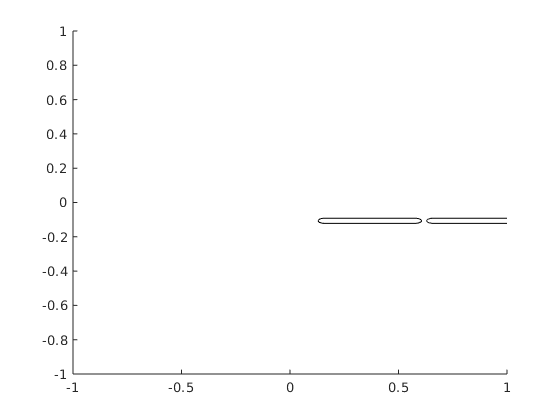

F = animate_asymmetric_solution(s, sol, gait);

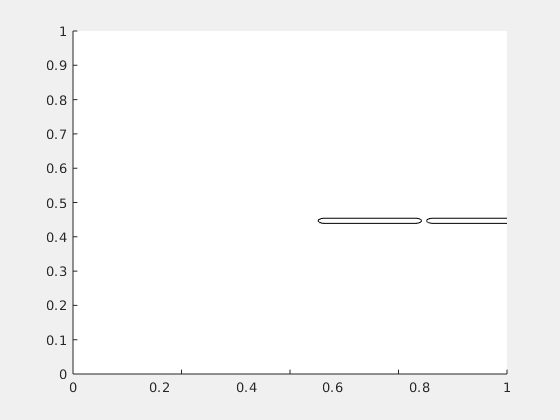

% play movie
figure('visible','on') %forces animation visible in live script
movie(F);

% write movie
% v = VideoWriter('AsymmetricFriction/animation_test_1link.avi');
% open(v);
% writeVideo(v, F);
% close(v);

% It's animating something!
% Things to do:
% - have body origin path traced out during animation
% - add motion blur
% - test with no-scales snake (physics check)
% - fix accumulation of gait displacement

% plot A as a function of alpha:
A = get_A_of_alpha(s, a_grid);

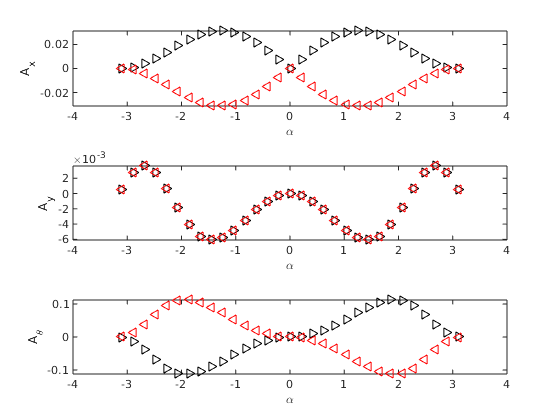

% directional glyphs
figure()
tiledlayout(3,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, A.positive(:,1), 'k>', a_grid, A.negative(:,1), 'r<');
ylabel(ax1,'A_x')
xlabel(ax1,'\alpha')

% Y plot
ax1 = nexttile;
plot(ax1,a_grid, A.positive(:,2), 'k>', a_grid, A.negative(:,2), 'r<');
ylabel(ax1,'A_y')
xlabel(ax1,'\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, A.positive(:,3), 'k>', a_grid, A.negative(:,3), 'r<');
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

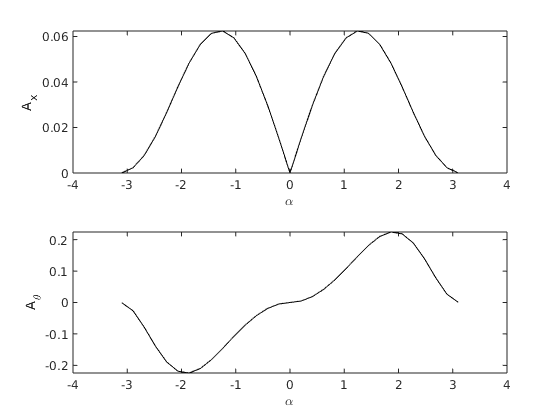


% directional glyphs
figure()
tiledlayout(2,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, A.difference(:,1),'k')
ylabel(ax1,'A_x')
xlabel(ax1, '\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, A.difference(:,3),'k')
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

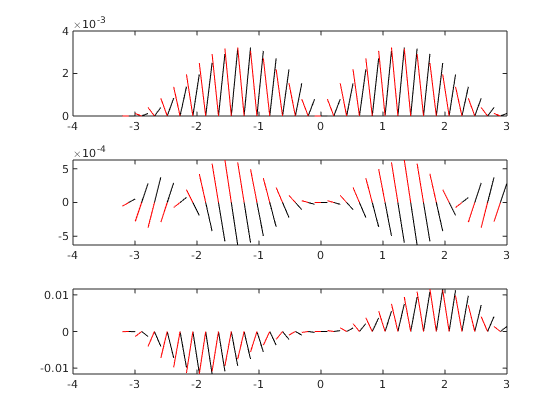

slope_plot(a_grid,A,true)

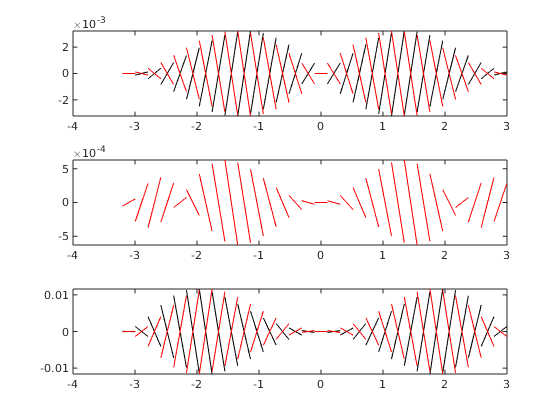

slope_plot(a_grid,A,false)

% compare a bunch of tiny gaits with different offsets
amp = 0.5;
step = 0.1;
off_grid = -pi+amp : step : pi-amp;

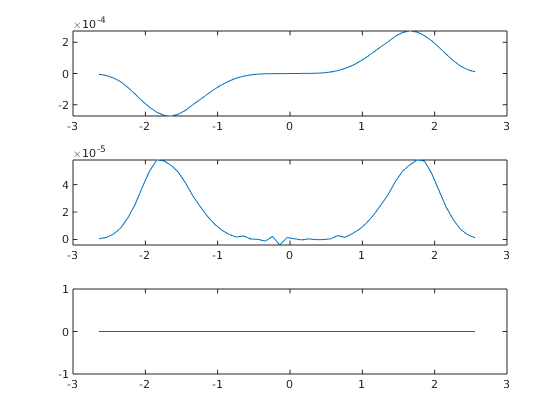

displacements = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    off = off_grid(i);
    gait = generate_1D_gait(amp, off, 1);
    sol = asym_solve_gait(s, gait, system_map);
    displacements(i,:) = deval(sol, 2*pi);
end
% figure()
% tiledlayout(3,1)
% ax = nexttile;
% plot(ax, off_grid, displacements(:,1))
% ax = nexttile;
% plot(ax, off_grid, displacements(:,2))
% ax = nexttile;
% plot(ax, off_grid, displacements(:,3))

% the backwards version:
displacements_bw = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    off = off_grid(i);
    gait = generate_1D_gait(0.5, off, -1);
    sol = asym_solve_gait(s, gait, system_map);
    displacements_bw(i,:) = deval(sol, 2*pi);
end
% figure()
% tiledlayout(3,1)
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,1))
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,2))
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,3))

% compare forwards and then backwards to backwards and then forwards
difference = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    fw = vec_to_mat_SE2(displacements(i, :));
    bw = vec_to_mat_SE2(displacements_bw(i, :));
    fw_then_bw = fw * bw;
    bw_then_fw = bw * fw;
    difference(i,:) = mat_to_vec_SE2(fw_then_bw) - mat_to_vec_SE2(bw_then_fw);
end
figure()
tiledlayout(3,1)
ax = nexttile;
plot(ax, off_grid, difference(:,1))
ax = nexttile;
plot(ax, off_grid, difference(:,2))
ax = nexttile;
plot(ax, off_grid, difference(:,3))